## Expected Result

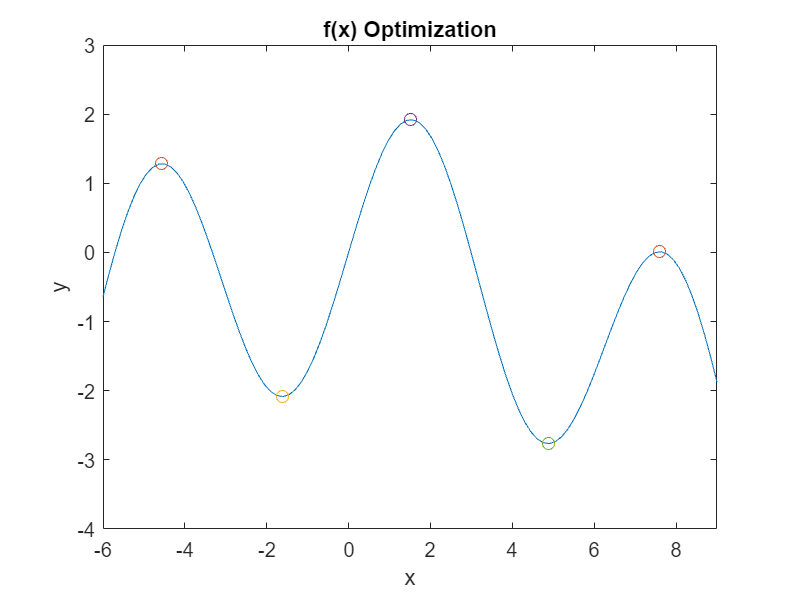

% Function
x = linspace(-6, 9, 100);
y = 2*sin(x)-(x.^2)/30;

% Values obtained through hand calculations:

% Local Max and Min
xLmax = [-4.56,7.598];
yLmax = 2*sin(xLmax)-(xLmax.^2)/30;

xLmin = -1.625;
yLmin = 2*sin(xLmin)-(xLmin.^2)/30;

% Global Max and Min
xGmax = 1.52;
yGmax = 2*sin(xGmax)-(xGmax.^2)/30;

xGmin = 4.876;
yGmin = 2*sin(xGmin)-(xGmin.^2)/30;

% Plotting expected results
figure;
plot(x, y);
hold on
plot(xLmax, yLmax, 'o');
plot(xLmin, yLmin, 'o');
plot(xGmax, yGmax, 'o');
plot(xGmin, yGmin, 'o');

xlabel('x');
ylabel('y');
xlim([-6 9]);
ylim([-4 3]);

title('f(x) Optimization');

## Golden Section Search

min = 1;
max = -1;
error = 0.001; % Stopping condition

tmp = cputime;
Part1 = [];
Part1(1,1:3) = goldenSectionSearch([-6 -3], max, error);
Part1(2,1:3) = goldenSectionSearch([-3 0], min, error);
Part1(3,1:3) = goldenSectionSearch([0 3], max, error);
Part1(4,1:3) = goldenSectionSearch([3 6], min, error);
Part1(5,1:3) = goldenSectionSearch([6 9], max, error);
GS_t = cputime - tmp;

T = array2table(Part1,'VariableNames',{'Xopt','f(Xopt)','N'},'RowNames',{'Max1','Min1','Max2','Min2','Max3'});
disp(T)

             Xopt      f(Xopt)     N 
            _______    ________    __

    Max1    -4.5588      1.2837    14
    Min1    -1.6251     -2.0851    16
    Max2     1.5204      1.9204    16
    Min2     4.8767     -2.7658    14
    Max3     7.5993    0.010508    13



### Bisection Search

tmp = cputime;
Part2 = [];
Part2(1,1:3) = bisectionSearch([-6 -3], error);
Part2(2,1:3) = bisectionSearch([-3 0], error);
Part2(3,1:3) = bisectionSearch([0 3], error);
Part2(4,1:3) = bisectionSearch([3 6], error);
Part2(5,1:3) = bisectionSearch([6 9], error);
BS_t = cputime - tmp;

T = array2table(Part2,'VariableNames',{'Xopt','f(Xopt)','N'},'RowNames',{'Max1','Min1','Max2','Min2','Max3'});
disp(T)

             Xopt      f(Xopt)     N 
            _______    ________    __

    Max1    -4.5615      1.2837     9
    Min1    -1.6245     -2.0851    10
    Max2      1.519      1.9204    10
    Min2     4.8779     -2.7658     9
    Max3     7.5996    0.010507     8



### Newton-Raphson Method

tmp = cputime;
Part3 = [];
Part3(1,1:3) = NewtonRaphsonMethod([-6 -3], -5.5, error);
Part3(2,1:3) = NewtonRaphsonMethod([-3 0], -2.5, error);
Part3(3,1:3) = NewtonRaphsonMethod([0 3], 0.5, error);
Part3(4,1:3) = NewtonRaphsonMethod([3 6], 4, error);
Part3(5,1:3) = NewtonRaphsonMethod([6 9], 7, error);
NR_t = cputime - tmp;

T = array2table(Part3,'VariableNames',{'Xopt','f(Xopt)','N'},'RowNames',{'Max1','Min1','Max2','Min2','Max3'});
disp(T)

             Xopt      f(Xopt)    N
            _______    _______    _

    Max1    -4.5598     1.2837    4
    Min1     -1.625    -2.0851    4
    Max2     1.5201     1.9204    4
    Min2     4.8756    -2.7658    4
    Max3     7.5979    0.01051    3



### Comparing Computational Time

disp("Golden Section Time [sec]:");

Golden Section Time [sec]:


disp(GS_t);

    0.0625



disp("Bisection Search Time [sec]:");

Bisection Search Time [sec]:


disp(BS_t);

    0.0312



disp("Newton-Raphson Method Time [sec]:");

Newton-Raphson Method Time [sec]:


disp(NR_t);

    0.0156

